## Rozkład t-Studenta - uzupełnienie informacji

Zmienna losowa Z ma rozkład normalny standaryzowany Z~N(0,1), $\chi^2$ - rozkład chi-kwadrat, k - liczba stopni swobody rozkładu.

Zmienna losowa utworzona jako:

$t=\frac{Z}{\sqrt{\chi^2 }}\sqrt{k}$ ,

ma rozkład t-Studenta z liczbą stopni swobody równą k.

[tpdf](https://www.mathworks.com/help/releases/R2020a/stats/tpdf.html) - *Student's t probability density function*

[tcdf](https://www.mathworks.com/help/releases/R2020a/stats/tcdf.html) - *Student's t cumulative distribution function*

[tinv](https://www.mathworks.com/help/releases/R2020a/stats/tinv.html) (*Student's t inverse cumulative distribution function*)

[pdf](https://www.mathworks.com/help/releases/R2020a/stats/prob.normaldistribution.pdf.html) (*Probability density function*) - wskazanie dla jakiego rozkładu

Funkcja **tinv (***Student's t inverse cumulative distribution function*) - odwrotnośc dystrybuanty

%web(fullfile(docroot, 'stats/tinv.html'))

Zasosowanie:

Zakładamy prawdopodobieństwo p

p = 0.95;   

przeprowadzamy obliczenia dla różnych wartości stopni swobody k

k = [1 3 5 7 10 15 20 25 30 50];   
t = tinv(p,k) %odpowiada t

t =     6.3138    2.3534    2.0150    1.8946    1.8125    1.7531    1.7247    1.7081    1.6973    1.6759


**Dwustronne wartości krytyczne**

Przykład

clear all; close all
p = 0.95;
k=7

k = 7

alpha = 1 - p; %poziom istotności alpha=0,05

**Poziom istotności** (**α**) – przyjęte z góry dopuszczalne ryzyko popełnienia [błędu I rodzaju](https://pl.wikipedia.org/wiki/B%C5%82%C4%85d_pierwszego_rodzaju) (uznania prawdziwej hipotezy zerowej za fałszywą),

pLo = alpha/2;
pUp = 1 - alpha/2;
crit = tinv([pLo pUp], k)

crit =    -2.3646    2.3646


wartość krytyczna 2,3646

Wizualizacja


t = -5:0.1:5;
k=7

k = 7

y2 = tpdf(t,k);
figure (1)
plot(t,y2,'LineWidth',2)
hold on
grid on
t1=crit(1,2)

t1 = 2.3646

t2=crit(1,1)

t2 = -2.3646

plot(t1,tpdf(t2,k),'r*')
plot(t2,tpdf(t2,k),'r*')
a = [t1 t1];
b = [0 tpdf(t1,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
a = [t2 t2];
b = [0 tpdf(t2,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t3 = t1:0.1:5;
y3 = tpdf(t3,k);
area(t3,y3,'FaceColor','b');
t4 = -5:0.1:t2

t4 =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000


y4 = tpdf(t4,k);
area(t4,y4,'FaceColor','g');
xlabel('Obserwacje (t)')
ylabel('Funkcja gęstości prawdopodobieństwa (pdf)')
title('Rozkład t-Studenta')
legend({'k='+ string(k),'t1='+ string(crit(1,1)),'t2='+ string(crit(1,2)),'granica 1','granica 2','p1','p2'})

x = [0.8 0.25];
y = [0.4 0.15];
annotation('textarrow',x,y,'String',string((1-p)/2*100)+ '%')

x = [0.8 0.75];
y = [0.4 0.05];
annotation('textarrow',x,y)

Przykład 

p = 0.99;
k=7

k = 7

alpha = 1 - p %poziom istotności alpha=0,01

alpha = 0.0100

pLo = alpha/2

pLo = 0.0050

pUp = 1 - alpha/2

pUp = 0.9950

crit = tinv([pLo pUp], k)

crit =    -3.4995    3.4995


Wartrość krytyczna równa jest 3,4995

p = 0.999;
k=7

k = 7

alpha = 1 - p %poziom istotności alpha=0,001

alpha = 0.0010

pLo = alpha/2

pLo = 5.0000e-04

pUp = 1 - alpha/2

pUp = 0.9995

crit = tinv([pLo pUp], k)

crit =    -5.4079    5.4079


Wartrość krytyczna równa jest 5,4079

p = 0.9999;
k=7

k = 7

alpha = 1 - p %poziom istotności alpha=0,0001

alpha = 1.0000e-04

pLo = alpha/2

pLo = 5.0000e-05

pUp = 1 - alpha/2

pUp = 1.0000

crit = tinv([pLo pUp], k)

crit =    -7.8846    7.8846


Wartrość krytyczna równa jest 7,8846

Przykład -zastosowania funkcji **ttest **

Określenie przedziału ufności CI (*confidence interval*)

opis

%web(fullfile(docroot, 'stats/ttest.html'))

przykład zastosowania:

mu = 10

mu = 10

sigma = 2

sigma = 2

n = 100

n = 100

rng default 
x1 = normrnd(mu,sigma,n,1)

x1 =    11.0753
   13.6678
    5.4823
   11.7243
   10.6375
    7.3846
    9.1328
   10.6852
   17.1568
   15.5389


xbar = mean(x1)

xbar = 10.2462

se = std(x1)/sqrt(n)

se = 0.2325

k = n - 1

k = 99

p = 0.95

p = 0.9500

alpha = 1 - p;
pLo = alpha/2;
pUp = 1 - alpha/2;
crit = tinv([pLo pUp], k);
CI1 = xbar + crit*se

CI1 =     9.7849   10.7075


[h,p,CI12] = ttest(x1,k,'Alpha',alpha)

h = 1

p = 1.1861e-158

CI12 =     9.7849
   10.7075


dla mniejszej liczby wygenerowanych wartosci losowych

mu = 10

mu = 10

sigma = 2

sigma = 2

n = 10

n = 10

rng default 
x2 = normrnd(mu,sigma,n,1)

x2 =    11.0753
   13.6678
    5.4823
   11.7243
   10.6375
    7.3846
    9.1328
   10.6852
   17.1568
   15.5389


xbar = mean(x2)

xbar = 11.2486

se = std(x2)/sqrt(n)

se = 1.1194

k = n - 1

k = 9

p = 0.95

p = 0.9500

alpha = 1 - p;
pLo = alpha/2;
pUp = 1 - alpha/2;
crit = tinv([pLo pUp], k);
CI2 = xbar + crit*se

CI2 =     8.7164   13.7808


[h,p,CI22] = ttest(x2,k,'Alpha',alpha)

h = 0

p = 0.0755

CI22 =     8.7164
   13.7808


Można zauważyć zwiększenie przedziału ufności!!!

Generator liczb pseudolosowych zgodnego z rozkładem statystycznym t-Studenta **trnd**

opis

%web(fullfile(docroot, 'stats/trnd.html'))

zastosowanie:

%rng('default')
rng('shuffle')
nu1 = ones(1,10);  % liczba stopni swobody
r1 = trnd(nu1)

r1 =    -2.0760    2.7649   -0.5548    0.8182    0.5688    0.2105   -0.8995    0.9235   -1.3113   -0.9761


r2 = trnd(10, [10 10])

r2 =     0.8719   -2.2212   -1.6106   -1.0015   -0.0678   -0.8063    2.2711    0.0507   -1.3400    0.1645
   -1.9164   -0.8121    0.4564    1.3399   -2.1362    1.5650    0.0109   -0.8753    0.5513    0.2703
    0.7479    0.1301   -0.0522    2.4258    0.1539   -1.5740    1.0905   -0.7538   -0.3441    1.6038
   -0.8244   -1.7385    0.1276   -0.9922    0.0891   -0.4434    1.7475    1.0496   -0.2377    0.2569
   -0.2079   -1.2782    1.2723    0.3314   -0.7625   -0.2091    0.3107    1.2061   -0.5483    0.1170
   -0.1281    0.4317    0.0425   -0.4589   -1.3962    1.0411   -1.1121   -0.4826    0.5130    0.9393
    1.5003    2.7858   -1.3593    0.6041   -0.7930    1.6871    1.8223   -0.3687    0.2551   -1.9069
    0.2918    0.7872    0.1074    0.0028   -1.4397    0.5624   -0.3263    0.1880   -1.3712    1.2722
    0.5373    0.4493    1.2025   -1.2953    0.7163    0.1881    0.9630   -1.7932    0.3238    0.7780
   -0.7968    1.2367   -0.0414   -0.6141   -0.7581   -0.3363   -0.1113    0.0052    1.

Zadanie 

oblicz prawdopodobieństwo, że zmienna losowa  o rozkładzie t-Studenta z liczbą stopni swobody 10 przyjmuje wartości większe lub równe 1,4 ?

$P\left(t\ge 1,4\right)$ = 1- $P\left(t\le 1,4\right)$

t=1.4

t = 1.4000

k=10

k = 10

Rówoważne wywołanie

p1=1-tcdf(t,k)

p1 = 0.0959

p1b=tcdf(t,k,'upper')

p1b = 0.0959

Szukane prawdopodobieństwo $P\left(t\ge 1,4\right)$ wynosi 0,0959

t = -5:0.1:5;
k=10

k = 10

y2 = tpdf(t,k);
figure (5)
plot(t,y2,'LineWidth',2)
hold on
grid on
t1=1.4

t1 = 1.4000

plot(t1,tpdf(t1,k),'r*')
a = [t1 t1];
b = [0 tpdf(t1,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t2 = t1:0.1:5;
y3 = tpdf(t2,k);
area(t2,y3,'FaceColor','b');
xlabel('Obserwacje (t)')
ylabel('Funkcja gęstości prawdopodobieństwa (pdf)')
title('Rozkład t-Studenta')
legend({'k = 10','t1=1.4','granica','p'})

Zadanie 

oblicz prawdopodobieństwo, że zmienna losowa  o rozkładzie t-Studenta z liczbą stopni swobody 10 przyjmuje wartości większe lub równe 1,4, lub mniejsze lub równe -1,4 ?

$P\left(\left|t\right|\ge 1,4\right)$ = $2\cdot \left(1-P\left(t\le 1,4\right)\right)$

obliczenie

t1=1.4

t1 = 1.4000

obliczenia równoważne

p2=2*(1-tcdf(t1,k))

p2 = 0.1918

p2b=2*tcdf(-t1,k)

p2b = 0.1918

p2c=tcdf(-t1,k)+tcdf(t1,k,'upper')

p2c = 0.1918

Wizualizacja

t = -5:0.1:5;
k=10

k = 10

y2 = tpdf(t,k);
figure (6)
plot(t,y2,'LineWidth',2)
hold on
grid on
t1=1.4

t1 = 1.4000

t2=-1.4

t2 = -1.4000

plot(t1,tpdf(t2,k),'r*')
plot(t2,tpdf(t2,k),'r*')
a = [t1 t1];
b = [0 tpdf(t1,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
a = [t2 t2];
b = [0 tpdf(t2,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t3 = t1:0.1:5;
y3 = tpdf(t3,k);
area(t3,y3,'FaceColor','b');
t4 = -5:0.1:t2

t4 =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000


y4 = tpdf(t4,k);
area(t4,y4,'FaceColor','g');
xlabel('Obserwacje (t)')
ylabel('Funkcja gęstości prawdopodobieństwa (pdf)')
title('Rozkład t-Studenta')

legend({'k='+ string(k),'t1='+ string(t1),'t2='+ string(t2),'granica 1','granica 2','p1','p2'})

x = [0.7 0.35];
y = [0.4 0.15];
annotation('textarrow',x,y,'String',string(p2*100)+ '%')

x = [0.7 0.67];
y = [0.4 0.15];
annotation('textarrow',x,y)


Szukane prawdopodobieństwo wynosi $P\left(\left|t\right|\ge 1,4\right)$ wynosi 0,1918

# Test istotności dla wartości średniej populacji [[wiki]](https://pl.wikipedia.org/wiki/Test_istotno%C5%9Bci_dla_warto%C5%9Bci_%C5%9Bredniej_populacji) o rozkładzie normalnym mała próba

clear all; close all; clc
zuzycie =[6.75
          7.75
          7.6
          7.05
          8.9
          8.25
          7.25
          8.25
          7.3
          7.2 %10
          7.5
          7.45
          7.75 %13
          7.85
          8.3
          8.25
          7.3
          6.5
          8.25
          8.45
          7.75
          8.8
          8.75
          7.1] %l/100km

zuzycie =     6.7500
    7.7500
    7.6000
    7.0500
    8.9000
    8.2500
    7.2500
    8.2500
    7.3000
    7.2000


      
      
n= size(zuzycie,1)

n = 24

xsr= mean(zuzycie) %empiryczna wartość średnia

xsr = 7.7625

s=std(zuzycie)

s = 0.6538

Spalanie podane przez producenta

m0=7.5 %l/100km

m0 = 7.5000

Obliczamy empiryczną wartość statystyki testowej (t Studenta)

temp=((xsr-m0)/s)*sqrt(n)

temp = 1.9670

Założony poziom istotności

alfa=0.02

alfa = 0.0200

k=n-1   

k = 23

talfa= tinv(1-alfa,k)

talfa = 2.1770



t = -5:0.1:5;

y2 = tpdf(t,k);
figure (1)
plot(t,y2,'LineWidth',2)
hold on
grid on
t1=talfa

t1 = 2.1770

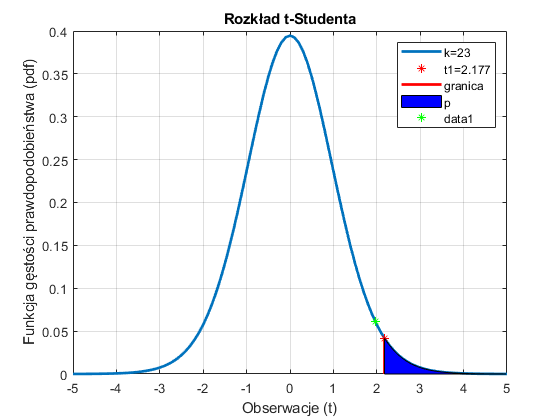

plot(t1,tpdf(t1,k),'r*')
a = [t1 t1];
b = [0 tpdf(t1,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)
t2 = t1:0.1:5;
y3 = tpdf(t2,k);
area(t2,y3,'FaceColor','b');
xlabel('Obserwacje (t)')
ylabel('Funkcja gęstości prawdopodobieństwa (pdf)')
title('Rozkład t-Studenta')

legend({'k='+ string(k),'t1='+ string(t1),'granica','p','temp'})

plot(temp,tpdf(temp,k),'g*')

Przykład

oblicz prawdopodobieństwo, że zmienna losowa  o rozkładzie t-Studenta z liczbą stopni swobody 10 przyjmuje wartości mniejsze lub równe -0,5 ?


$$P\left(t\le -0,5\right)$$


t3=-0.5

t3 = -0.5000

k=10

k = 10

p3=tcdf(t3,k)

p3 = 0.3139

wizualizacja

t= -5:0.1:5;
k=10

k = 10

y = tpdf(t,k);
figure (7)
plot(t,y,'LineWidth',2)
hold on
grid on
t3=-0.5

t3 = -0.5000


plot(t3,tpdf(t3,k),'r*')

a = [t3 t3];
b = [0 tpdf(t3,k)];
line(a,b,'Color','red','LineStyle','-','LineWidth',2)

t4 = -5:0.1:t3

t4 =    -5.0000   -4.9000   -4.8000   -4.7000   -4.6000   -4.5000   -4.4000   -4.3000   -4.2000   -4.1000   -4.0000   -3.9000   -3.8000   -3.7000   -3.6000   -3.5000   -3.4000   -3.3000   -3.2000   -3.1000   -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000


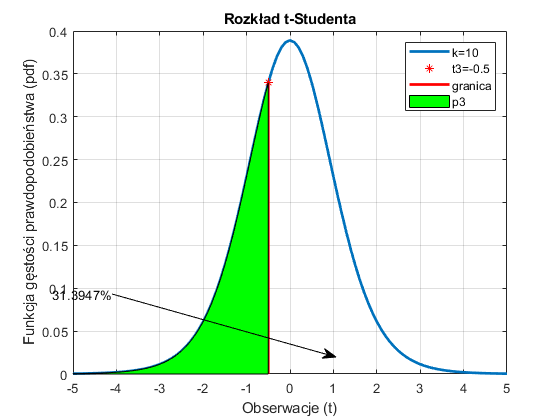

y4 = tpdf(t4,k);
area(t4,y4,'FaceColor','g');

xlabel('Obserwacje (t)')
ylabel('Funkcja gęstości prawdopodobieństwa (pdf)')
title('Rozkład t-Studenta')


legend({'k='+ string(k),'t3='+ string(t3),'granica','p3'})

x = [0.2 0.6];
y = [0.3 0.15];
annotation('textarrow',x,y,'String',string(p3*100)+ '%')

Szukane prawdopodobieństwo wynosi $P\left(t\le -0,5\right)$ wynosi p3=0,3139